% 温度补偿代码，预计采用两种形式：两点补偿，多项式拟合。
% 加载颜色集
run("Color.m");

% 两点校正法，根据一下公式求得个点的校正系数和校正常量，带入带入测量计算即可。
% b = (y2 - kx2) 或 b = (y1 - kx1)
% k = (y2 - y1) / (x2 - x1)

% 载入两点校正数据
run("Twopointcalibrationdataload.m"); 

文件数量正常，正在加载数据



% 初始化系数数组
coefficient_and_constant = zeros(2,7);

% 计算各点的系数和常量
for i = 1:1:7
    coefficient_and_constant(1, i) = (average_wafer_data(1, i) - average_wafer_data(2, i)) / (average_heater_data(1, i) - average_heater_data(2, i));
    coefficient_and_constant(2, i) = (average_wafer_data(1, i) - (coefficient_and_constant(1, i) * average_heater_data(1, i)));
end

% 转化为六位小数
str_cac = strings(2,7);
for i = 1:1:7
    for j = 1:1:2
        str_cac(j, i) = sprintf("%.6f",coefficient_and_constant(j, i));
    end
end


y1 = coefficient_and_constant(1,1) * average_heater_data(2, 1) + coefficient_and_constant(2, 1)

y1 = 27.3282

y2 = coefficient_and_constant(1,1) * average_heater_data(1, 1) + coefficient_and_constant(2, 1)

y2 = 150.3973

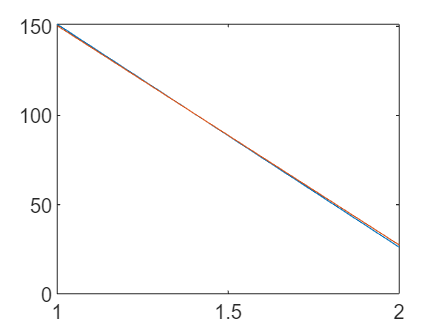

X = linspace(1,2,2);

figure;
plot(X,average_heater_data(:,1));
hold on;
plot(X,average_wafer_data(:,1));
set(gca,'Box','off', ...                                % 边框开关
    'LineWidth',1, ...                                  % 线宽（非数据线）
    'XGrid','off','YGrid','on', ...                     % 网格开关
    'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
    'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
    'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
colororder(color1002);
legend;


